# Unidad 6 - TP08b

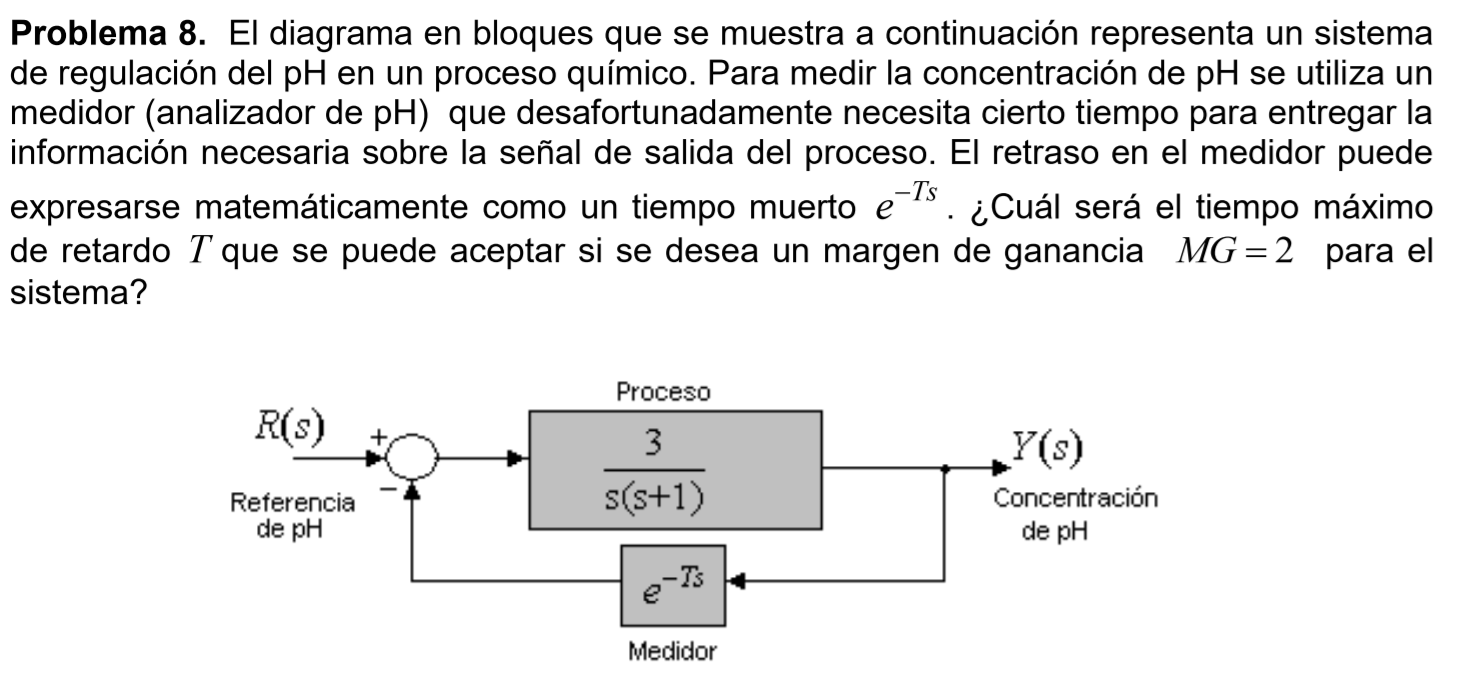

## Requisitos

- 
$${\mathrm{MG}}_{\mathrm{dB}} =2\;\mathrm{dB}$$


- 
$$\mathrm{MG}=0\ldotp 7943$$


## Diseño


$$G\left(s\right)H\left(s\right)=\frac{3{\;e}^{-\mathrm{sT}} }{s\left(s+1\right)}$$


$\left|G\left(s\right)H\left(s\right)\right|=\frac{3\;\left|e^{-\mathrm{sT}} \right|}{\left|s\right|\;\left|s+1\right|}$; $\left|e^{-\mathrm{sT}} \right|=1$


$$\left|G\left(w\right)H\left(w\right)\right|=\frac{3}{\left|w\right|\;\left|1+\mathrm{jw}\right|}$$



$$\left|G\left(w\right)H\left(w\right)\right|=\frac{3}{\left|w\right|\;\sqrt{1+w^2 }}$$


Aplicando las condiciones de diseño


$$\mathrm{MG}=\frac{3}{\left|w_x \right|\;\sqrt{1+w_x^2 }}$$



$${\mathrm{MG}}^2 =\frac{9}{w_x^2 \;\left(1+w_x^2 \right)}$$



$$w_x^2 \left(1+w_x^2 \right)=\frac{9}{{\mathrm{MG}}^2 }$$



$$w_x^4 +w_x^2 \;-\frac{9}{{\mathrm{MG}}^2 }=0$$


clear;
MG_dB = 2;
MG = 10^(-MG_dB/20);
wx = roots([1 0 1 0 (-9/MG^2)])

La única raíz que nos interesa es la real y positiva.

Entonces analizaremos la fase,


$$\phi \left(w\right)=-\mathrm{wT}-\frac{\pi }{2}-\mathrm{atg}\left(\frac{w}{1}\right)$$


Como estamos analizando el MG,


$$-\pi =-w_x T-\frac{\pi }{2}-\mathrm{atg}\left(\frac{w_x }{1}\right)$$



$$w_x T\;=\pi -\frac{\pi }{2}-\mathrm{atg}\left(w_x \right)$$



$$T\;=\frac{\frac{\pi }{2}-\mathrm{atg}\left(w_x \right)}{w_x }$$


T = ( (pi/2) - atan(wx(4))) / (wx(4))

## Verificación

s = tf('s');
G = 3/(s*(s+1));
H = exp(-s*T);

% Diagrama de bode.
bode(G*H);
grid on;